##                                                         Questões P1 provas anteriores

import RoboticaBiblioteca.*
printListaManipuladores()

--------------------> Lista de Manipuladores <-----------------------
1 - Manipulador Cartesiano: PPP
   1.1 - Manipulador Pórtico: cartesianos, mas com base em suportes
2 - Manipulador Cilíndrico: RPP
3 - Manipulador Articulados/Antropomórficos: RRR
4 - Manipulador Esféricos/Polares: RRP
5 - Manipulador SCARA: RRP, diferente do esférico, tem três eixos z0,
                       z1 e z2 todos verticais e paralelos


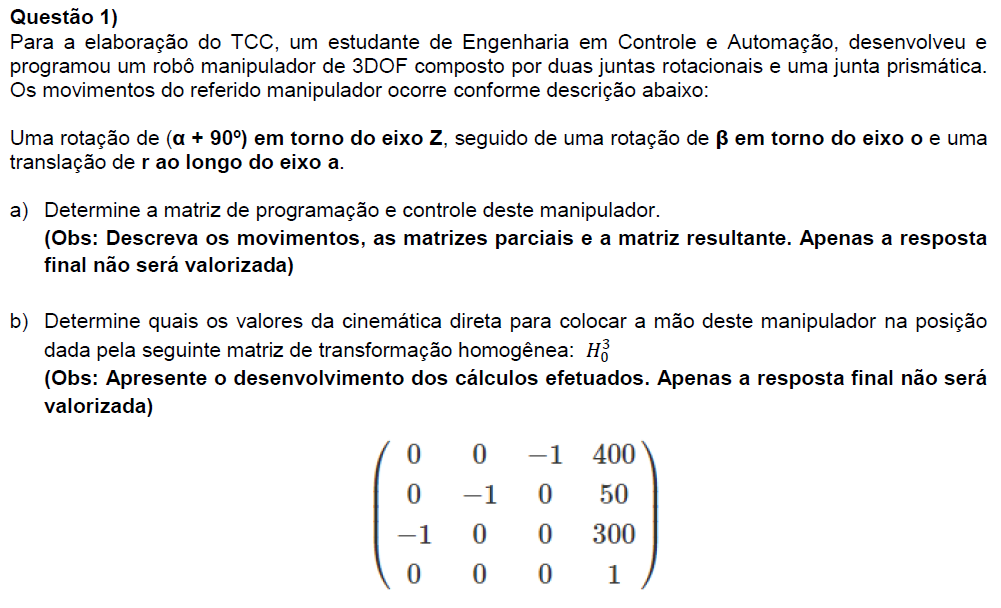

**a) **R: rot('z',alpha)*rot('z',90)*rot('y',beta)*trans(0,0,r)

syms alpha beta r;
% rot('z',alpha + 90)*rot('y',beta)*trans(0,0,r) -> separar pois estão no mesmo eixo
rot('z',alpha)

$$ans = \left(\begin{array}{cccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & 0\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

rot('z',90)

ans =      0    -1     0     0
     1     0     0     0
     0     0     1     0
     0     0     0     1


rot('y',beta)

$$ans = \left(\begin{array}{cccc} \cos\left(\beta \right) & 0 & \sin\left(\beta \right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

trans(0,0,r)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & r\\ 0 & 0 & 0 & 1 \end{array}\right)$$

rot('z',alpha)*rot('z',90)*rot('y',beta)*trans(0,0,r)

$$ans = \left(\begin{array}{cccc} -\cos\left(\beta \right)\,\sin\left(\alpha \right) & -\cos\left(\alpha \right) & -\sin\left(\alpha \right)\,\sin\left(\beta \right) & -r\,\sin\left(\alpha \right)\,\sin\left(\beta \right)\\ \cos\left(\alpha \right)\,\cos\left(\beta \right) & -\sin\left(\alpha \right) & \cos\left(\alpha \right)\,\sin\left(\beta \right) & r\,\cos\left(\alpha \right)\,\sin\left(\beta \right)\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) & r\,\cos\left(\beta \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**b)**

**-r*sen(alpha)*sen(beta) = 400----                                      **$\tan \;x=\frac{\mathrm{sen}\;x}{\cos \;x}$

**r*cos(alpha)*sen(beta) = 50 ----**

**r*cos(beta) = 300**

**alpha = tg^-1(-400/50) = -82.875**

alpha = atan2d(-400,50)

alpha = -82.8750

**r*sen(beta) = 50/cos(-82.8) = 403.11**

rsb = 50/cosd(-82.875)

rsb = 403.1138

**beta = tg^-1(403.11/300) = 53.34**

beta = atan2d(403.11,300)

beta = 53.3429

**r = 300/cos(53.34) = 502.49**

r = 300/cosd(53.34)

r = 502.4576

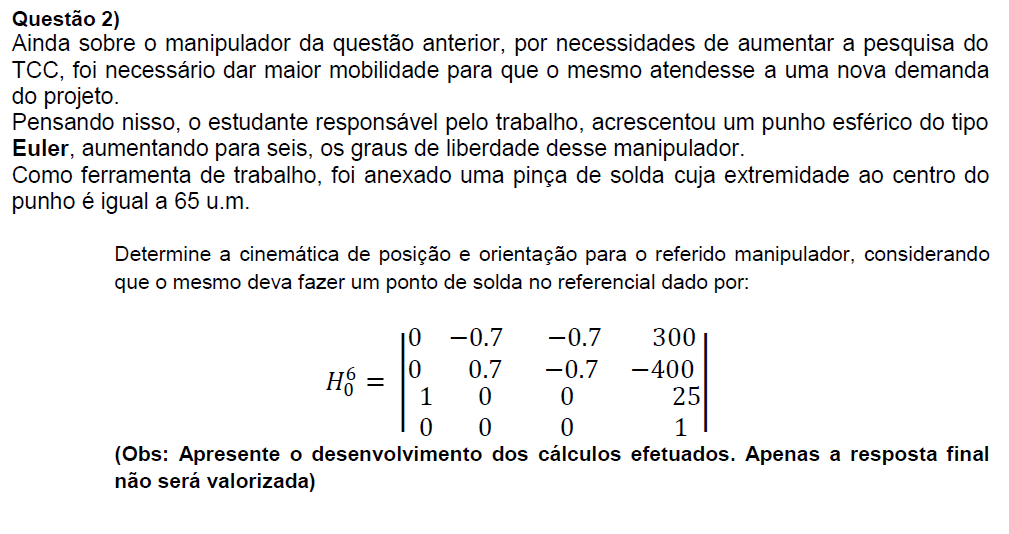


$$p_c =d_0^6 -d_6 \cdot R_0^6 \cdot k$$


H06 = [0 -0.7 -0.7 300;
       0 0.7 -0.7 -400;
       1 0 0 25;
       0 0 0 1];
d06 = H06(1:3,4)

d06 =    300
  -400
    25


d6 = 65;
R06 = H06(1:3,1:3)

R06 =          0   -0.7000   -0.7000
         0    0.7000   -0.7000
    1.0000         0         0


pc = PC(d06,d6,R06)

pc =   345.5000
 -354.5000
   25.0000


Determinando a cinemática de posição

**-r*sen(alpha)*sen(beta) = 345.5----**

**r*cos(alpha)*sen(beta) = -354.5----**

**r*cos(beta) = 25**

**alpha = tg^-1(-345.5/-354.5) = -135.7366**

alpha = atan2d(-pc(1,1),pc(2,1))

alpha = -135.7366

**r*sen(beta) = -354.5/cos(alpha) = 495.0157**

rsb = pc(2,1)/cosd(alpha)

rsb = 495.0157

**beta = tg^-1(495.0157/25) = 87.1088**

beta = atan2d(rsb,pc(3,1))

beta = 87.1088

**r = 25/cos(87.1088) = 495.6465**

r = pc(3,1)/cosd(beta)

r = 495.6465

Determinando a cinemática de orientação

T03 = rot('z',alpha)*rot('z',90)*rot('y',beta)*trans(0,0,r)

T03 =     0.0352    0.7161    0.6971  345.5000
   -0.0361    0.6980   -0.7152 -354.5000
   -0.9987         0    0.0504   25.0000
         0         0         0    1.0000


R03 = T03(1:3,1:3)

R03 =     0.0352    0.7161    0.6971
   -0.0361    0.6980   -0.7152
   -0.9987         0    0.0504


R06 = H06(1:3,1:3)

R06 =          0   -0.7000   -0.7000
         0    0.7000   -0.7000
    1.0000         0         0


R06 = R03*R36

R36 = (R03)^-1 * R06

R36 = (R03)^-1 * R06

R36 =    -0.9987   -0.0499    0.0006
   -0.0000   -0.0127   -0.9899
    0.0504   -0.9886    0.0127


T36 = [R36, zeros(3,1);
       zeros(1,3)  1];
angsEuler(T36);

phi = -89.962843 | theta = 89.271713 | psi = -92.920722


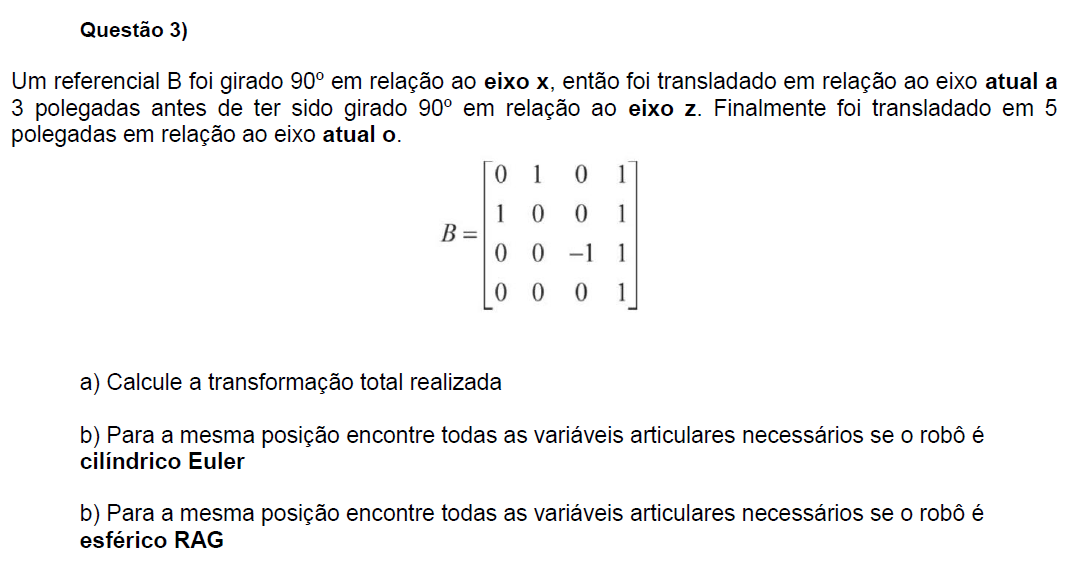

**a) rot('z',90)*rot('x',90)*B*trans(0,0,3)*trans(0,5,0)**

B = [0 1 0 1;
     1 0 0 1;
     0 0 -1 1;
     0 0 0 1];
matriz4x4 = rot('z',90)*rot('x',90)*B*trans(0,0,3)*trans(0,5,0)

matriz4x4 =      0     0    -1    -2
     0     1     0     6
     1     0     0     1
     0     0     0     1


**b) **cilindrico - Euler

syms r alpha L;
Tcil(r,alpha,L)

$$ans = \left(\begin{array}{cccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & r\,\cos\left(\alpha \right)\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & r\,\sin\left(\alpha \right)\\ 0 & 0 & 1 & L\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**r*cos(alpha) = 2----**

**r*sen(alpha) = 6 ---- **

**L = 1**

[r, alpha, L] = movimentosTcil(-2,6,1);

r = 6.324555 | alpha = 108.434949 | L = 1.000000


[phi, theta, psi] = angsEuler(matriz4x4);

phi = 180.000000 | theta = 90.000000 | psi = 180.000000


phi = thetaA

theta = thetaO

psi = thetaN

**C) **esferico - RAG

syms r beta gama;
Tesf(r,beta,gama)

$$ans = \left(\begin{array}{cccc} \cos\left(\beta \right)\,\cos\left(\mathrm{gama}\right) & -\sin\left(\mathrm{gama}\right) & \cos\left(\mathrm{gama}\right)\,\sin\left(\beta \right) & r\,\cos\left(\mathrm{gama}\right)\,\sin\left(\beta \right)\\ \cos\left(\beta \right)\,\sin\left(\mathrm{gama}\right) & \cos\left(\mathrm{gama}\right) & \sin\left(\beta \right)\,\sin\left(\mathrm{gama}\right) & r\,\sin\left(\beta \right)\,\sin\left(\mathrm{gama}\right)\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) & r\,\cos\left(\beta \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**r*cos(gama)*sen(beta) = 2----**

**r*sen(beta)*sen(gama) = 6 ---- **

**r*cos(beta) = 1**

[r, beta, gama] = movimentosTesf(-2,6,1);

r = 6.403124 | beta = 81.015123 | gamma = 108.434949


[thetaN, thetaO, thetaA] = angsRAG(matriz4x4);

ThetaN = -0.000000 | ThetaO = -90.000000 | ThetaA = 0.000000


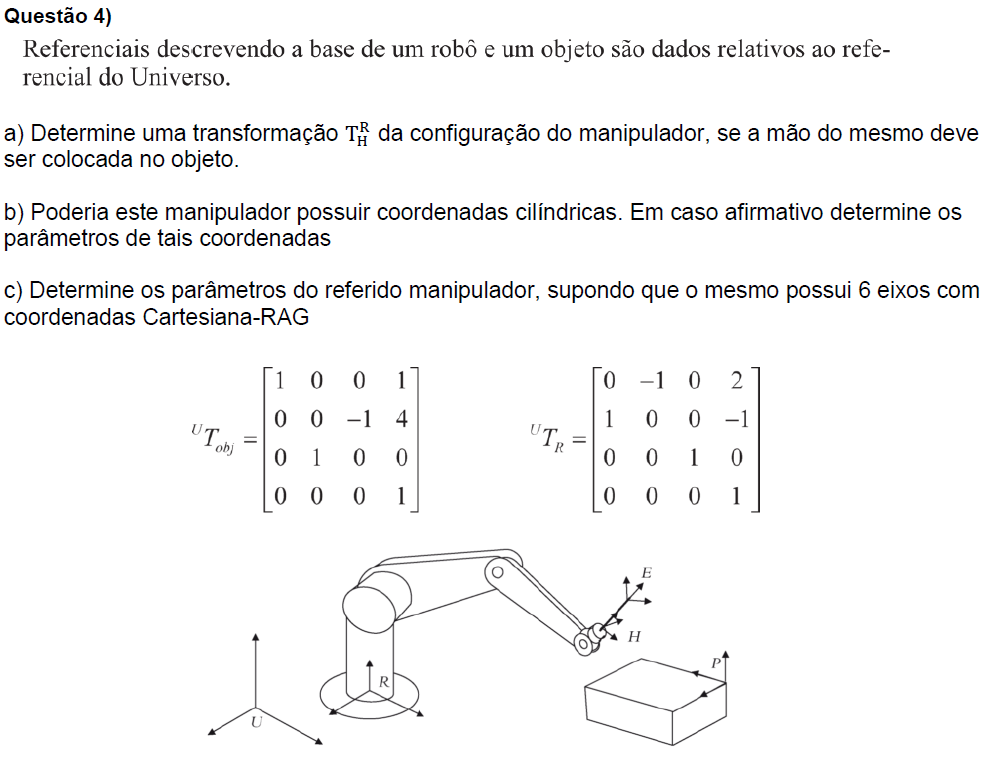

**a) se a mão do mesmo deve ser colocada no objeto -> H = Obj**

**UTH = UTR * RTH --> (UTR)^-1 * UTH = (UTR)^-1 * UTR * RTH**

**RTH = (UTR)^-1 * (UTH)**

**UTObj**

**UTR  --------->  RTU = (UTR)^-1**

UTObj = [1 0 0 1;
         0 0 -1 4;
         0 1 0 0;
         0 0 0 1];
UTR = [0 -1 0 2;
       1 0 0 -1;
       0 0 1 0;
       0 0 0 1];
RTH = (UTR^-1)*UTObj

RTH =      0     0    -1     5
    -1     0     0     1
     0     1     0     0
     0     0     0     1


**b) Não pode ser considerado cilindrico porque o terceiro elemento da primeira linha deve ser necessariamente 0 e não -1.**

syms r alpha L;
Tcil(r, alpha, L)

$$ans = \left(\begin{array}{cccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & r\,\cos\left(\alpha \right)\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & r\,\sin\left(\alpha \right)\\ 0 & 0 & 1 & L\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**c) **Cartesiano - RAG

[Px, Py, Pz] = movimentosTcart(5,1,0);

Px = 5.000000 | Py = 1.000000 | Pz = 0.000000


[thetaN, thetaO, thetaA] = angsRAG(RTH);

ThetaN = 90.000000 | ThetaO = -0.000000 | ThetaA = -90.000000
